# Демодуляция. Часть 2.

# Double Sideband Suppressed Carrier 

# (AM-DSB-SC)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Когерентная демодуляция с помощью схемы Костаса

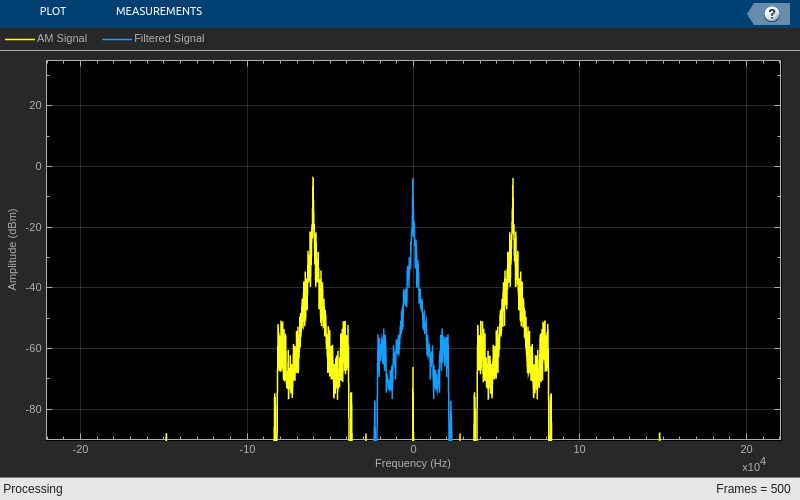

clc; clear; close all;
addpath('matlab/DSB_SC');

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 3;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

% расстройка по частоте (Hz)
FreqOffset = 1000;

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_SC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% фапч для восстановления несущей
% параметры фапч зависят от амплитуды входного сигнала
% его амплитуда меняется поэтому берем среднее значение, равное 0.27
CostasPLL = CostasAmSignalPLL( ...
    'SampleFrequency', SignalFs, ...
    'NoiseBandwidth', 100, ...
    'Dampingfactor', 0.7, ...
    'CentralFrequency', Fc + FreqOffset, ...
    'SignalAmp', 0.0012 ...
    );

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Baseband Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и выделение синфазного канала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1);

    % восстанавливаем несущую
    [BasebandSignal, Offset] = CostasPLL(AmSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp * DownSampler(BasebandSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal BasebandSignal]);
kd = 1; 
    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

% проигрывание полученного сообщения
sound(Message, AudioFs);

### 2. Когерентная демодуляция с помощью схемы Костаса при квадратурном приеме

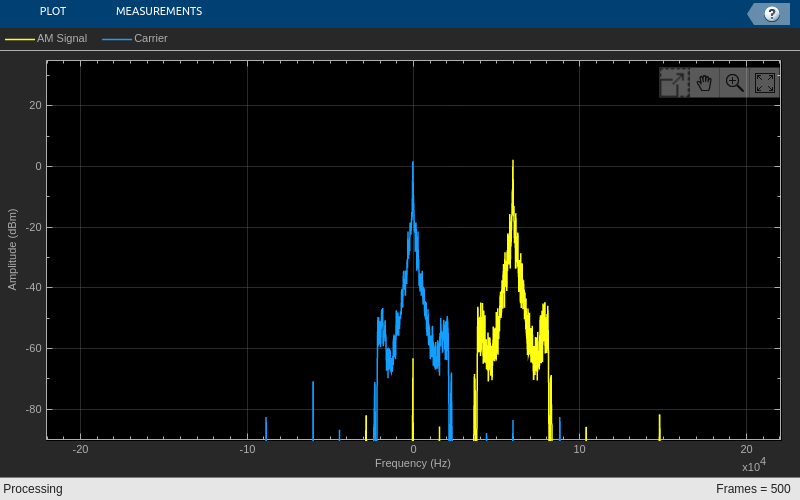

clc; clear; close all;

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 1;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

% расстройка по частоте (Hz)
FreqOffset = 1000;

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_SC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% фапч для восстановления несущей
CostasPLL = CostasAmComplexPLL( ...
    'SampleFrequency', SignalFs, ...
    'NoiseBandwidth', 100, ...
    'Dampingfactor', 0.7, ...
    'CentralFrequency', Fc + FreqOffset, ...
    'SignalAmp', 0.0012 ...
    );

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Baseband Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и формирование комплексного сигнала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1) + 1j*AmSignal(:,2);

    % восстанавливаем несущую
    [BasebandSignal, Offset] = CostasPLL(AmSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp * DownSampler(BasebandSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal BasebandSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

% проигрывание полученного сообщения
sound(Message, AudioFs);

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR

- M. Rice Digital Communications. A Discrete Time Approach

- B. Sclar Digital Communications. Fundamentals and Applications